## Metabolic and regulatory networks

## Computer practical course

Simon Hegele

Day 1

### Exercice 1


$$v = \frac{{v_{\text{max}} \cdot S}}{{(K_m + S)(1 + \frac{S}{K_i})}}$$


% Defining symbols
syms v(S) vmax S Km Ki

% Excluding negative values for S since negative concentrations are
% biologically irrelevant
assume(S >= 0)

% Defining the differential equation
v(S) = (vmax*S)/((Km+S)*(1+S/Ki))

$$v(S) = \frac{S\,\mathrm{vmax}}{\left(\frac{S}{\mathrm{Ki}}+1\right)\,\left(\mathrm{Km}+S\right)}$$

a) Plotting for  $K_m=9, v_{\text{max}}=5, K_i=4$

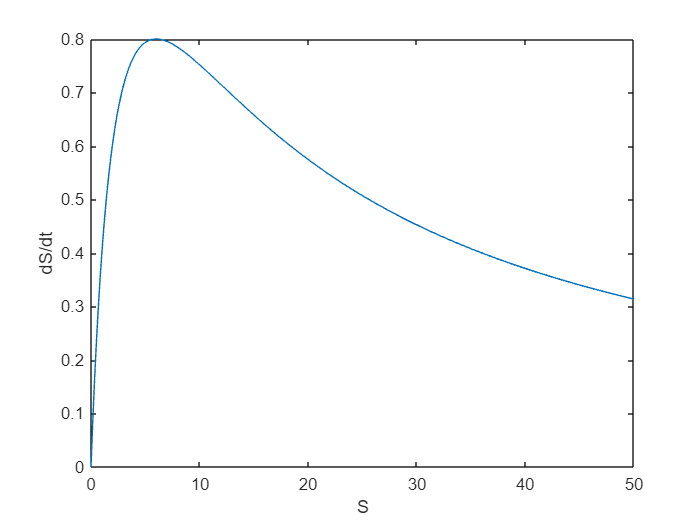

fplot(subs(v, {Km,vmax,Ki},{9,5,4}), [0,50])
xlabel('S');
ylabel('dS/dt')

b) Find $S$ such that $\frac{dS}{dt}$ is maximal for the given parameters

$\rightarrow$from the plot it is apparent that there is only one extreme which is the maximum

solve(diff(subs(v, {Km,vmax,Ki},{9,5,4})), S)

$$ans = 6$$

c) Find $S$ such that $\frac{dS}{dt}$ is maximal for any parameters

solve(diff(v) == 0, S)

$$ans = \sqrt{\mathrm{Ki}\,\mathrm{Km}}$$

### **Exercice 2**

a) Perform a regression analysis for hypothtical experimental data by fitting the Michaelis-Menten-equation

S_values = [0.100, 0.300, 1.000, 2.000, 2.900, 4.100, 7.000, 10.000]

S_values =     0.1000    0.3000    1.0000    2.0000    2.9000    4.1000    7.0000   10.0000


v_values = [0.055, 0.121, 0.240, 0.425, 0.456, 0.522, 0.584,  0.805]

v_values =     0.0550    0.1210    0.2400    0.4250    0.4560    0.5220    0.5840    0.8050


Km      2.9063

vmax    0.9402

Goodness of Fit:

R-square    0.9620

b) Perform a linear regression analysis in a Lineweaver-Burk-plot

rec_S_values = 1./S_values

rec_S_values =    10.0000    3.3333    1.0000    0.5000    0.3448    0.2439    0.1429    0.1000


rec_v_values = 1./v_values

rec_v_values =    18.1818    8.2645    4.1667    2.3529    2.1930    1.9157    1.7123    1.2422


Km      0.9871    

vmax    0.5862    

Goodness of Fit

R-square    0.9907

$\rightarrow$ We observe huge differences in the resulting values

c) Excliding an outlier

Excluding the last measuring point changes the results the most, so it is the least consistent with the rest of the data

For a): 

Km      1.6853

vmax    0.7312

Goodness of Fit

R-square    0.9912

For b): 

Km      1.4838

vmax    0.7051

Goodness of Fit

R-square    0.9831